syms t w;
f(t,w) = 1 + w/t;
y(t) = t*log(t) + 2*t;

for h=[1/10, 1/20, 1/40]
    [~, y_values] = Exact_Values(h, y);
    [t_values, w_values] = Adams_4th_Order_Predictor_Corrector(h, f);
    [error_values, max_error] = Error(y_values, w_values);
    fprintf('----------------------------------------------------\n');
    fprintf('Adams 4th-order predictor-corrector method with h=1/%d:\n', 1/h);
    fprintf('Approximated values are:\n');
    disp(w_values)
    fprintf('Absolute errors for each values are\n');
    disp(error_values);
    fprintf('Maximum absolute error is: %e\n', max_error)
end

----------------------------------------------------


Adams 4th-order predictor-corrector method with h=1/10:


Approximated values are:


    2.0000    2.3048    2.6188    2.9411    3.2711    3.6082    3.9520    4.3021    4.6580    5.0195    5.3863



Absolute errors for each values are


   1.0e-05 *

         0    0.0272    0.0485    0.0661    0.1046    0.1388    0.1693    0.1968    0.2222    0.2457    0.2679



Maximum absolute error is: 2.679057e-06


----------------------------------------------------


Adams 4th-order predictor-corrector method with h=1/20:


Approximated values are:


    2.0000    2.1512    2.3048    2.4607    2.6188    2.7789    2.9411    3.1051    3.2711    3.4388    3.6082    3.7793    3.9520    4.1263    4.3021    4.4793    4.6580    4.8381    5.0195    5.2023    5.3863



Absolute errors for each values are


   1.0e-06 *

         0    0.0094    0.0176    0.0249    0.0488    0.0704    0.0900    0.1079    0.1245    0.1399    0.1543    0.1678    0.1807    0.1929    0.2046    0.2158    0.2266    0.2371    0.2473    0.2572    0.2668



Maximum absolute error is: 2.668425e-07


----------------------------------------------------


Adams 4th-order predictor-corrector method with h=1/40:


Approximated values are:


    2.0000    2.0753    2.1512    2.2277    2.3048    2.3825    2.4607    2.5395    2.6188    2.6986    2.7789    2.8598    2.9411    3.0229    3.1051    3.1879    3.2711    3.3547    3.4388    3.5233    3.6082    3.6935    3.7793    3.8655    3.9520    4.0390    4.1263    4.2140    4.3021    4.3905    4.4793    4.5685    4.6580    4.7479    4.8381    4.9286    5.0195    5.1107    5.2023    5.2941    5.3863



Absolute errors for each values are


   1.0e-07 *

         0    0.0031    0.0060    0.0087    0.0193    0.0294    0.0388    0.0477    0.0562    0.0642    0.0718    0.0791    0.0860    0.0927    0.0991    0.1052    0.1112    0.1169    0.1224    0.1278    0.1330    0.1381    0.1430    0.1479    0.1526    0.1572    0.1617    0.1661    0.1704    0.1747    0.1788    0.1830    0.1870    0.1910    0.1949    0.1988    0.2027    0.2064    0.2102    0.2139    0.2176



Maximum absolute error is: 2.175862e-08


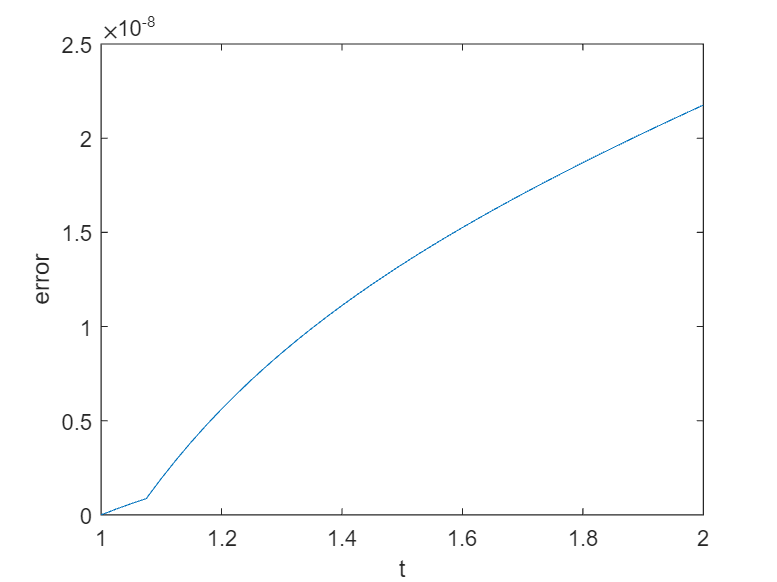


% last t_values and error_values are saved
% they are values associated with h=1/40
plot(t_values, error_values)
xlabel('t');
ylabel('error');

function [t_values, w_values] = Adams_4th_Order_Predictor_Corrector(h, f)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    w_values = zeros(1, numbs);

    t = 1;
    w = 2;
    w_values(1) = w;

    % RK4 for starting values
    for i=2:4
        K1 = h * f(t,w);
        K2 = h * f(t+h/2, w+K1/2);
        K3 = h * f(t+h/2, w+K2/2);
        K4 = h * f(t+h, w+K3);
        w = w + (K1+2*K2+2*K3+K4)/6;
        t = t + h;

        w_values(i) = w;
    end

    % Set starting pts
    w0 = w_values(1);
    w1 = w_values(2);
    w2 = w_values(3);
    w3 = w_values(4);
    t0 = t_values(1);
    t1 = t_values(2);
    t2 = t_values(3);
    t3 = t_values(4);

    % Do predictor corrector method
    for i=5:numbs
        t = t + h;
        % predict w_i
        w = w3 + h*(55*f(t3,w3)-59*f(t2,w2)+37*f(t1,w1)-9*f(t0,w0))/24;
        % correct w_i
        w = w3 + h*(9*f(t,w)+19*f(t3,w3)-5*f(t2,w2)+f(t1,w1))/24;

        w_values(i) = w;

        % reset w's and t's
        t0 = t1;
        t1 = t2;
        t2 = t3;
        t3 = t;
        w0 = w1;
        w1 = w2;
        w2 = w3;
        w3 = w;
    end
end

function [t_values, y_values] = Exact_Values(h, y)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    y_values = zeros(1, numbs);

    t = 1;
    for i=1:numbs
        y_values(i) = y(t);
        t = t + h;
    end
end

function [error_values, max_error] = Error(exact_values, approx_values)
    error_values = abs(exact_values - approx_values);
    max_error = max(error_values);
end